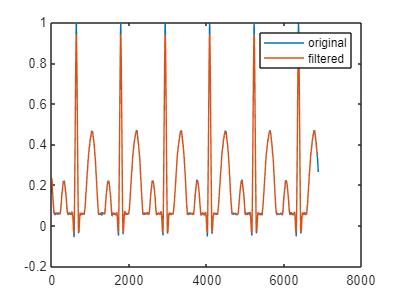

%question 2
Wp = 10/360; Ws = 20/360;
[n,Wn] = buttord(Wp,Ws,1,40);
[b,a] = butter(n,Wn);
data=load('ECG_Data.txt');
figure;
plot(data)
hold on 
plot(filtfilt(b, a, data))
legend('original','filtered')